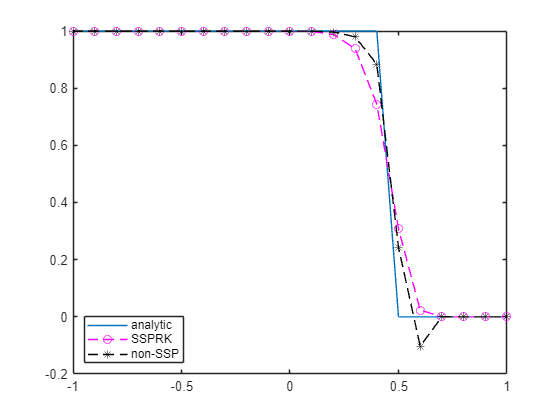

heaviside = @(x) 1.*(x>=0);
dx = 0.1; xMin = -1; xMax = 1; xs = xMin:dx:xMax;
t0 = 0; t_f = 1; N = 20; dh = abs(t_f-t0)/N;
u0 = xs; u0 = 1.*(u0 < 0);
f = @(t, u) [0, ((reshape(u(1:end-1), 1, length(u)-1).^2)./2-(reshape(u(2:end), 1, length(u)-1).^2)./2)./dx]';
[h, ts, ys] = RKsolver(f, u0, t0, t_f, N, 'SSPRK22');
[h2, ts2, ys2] = RKsolver(f, u0, t0, t_f, N, 'twoStepTest');
for i=1:N+1
    plot(xs, 1-heaviside(xs-ts(i)/2))
    hold on
    plot(xs, ys(:,i), 'mo--')
    plot(xs, ys2(:,i), 'k*--')
    legend('analytic', 'SSPRK', 'non-SSP', 'Location', 'southwest')
    hold off
    pause(0.1)
    drawnow
end

heaviside = @(x) 1.*(x>=0);
dx = 0.01; xMin = -1; xMax = 1; xs = xMin:dx:xMax;
t0 = 0; t_f = 1; N = 40; dh = abs(t_f-t0)/N;
u0 = xs; u0 = 1.*(u0 < 0);
f = @(t, u) [0, ((reshape(u(1:end-1), 1, length(u)-1).^2)./2-(reshape(u(2:end), 1, length(u)-1).^2)./2)./dx]';
tic
[h, ts, ys] = explicitRK(f, u0, t0, t_f, N, [0], [1]);
err1 = norm(ys(:,end)-(1-heaviside(xs-t_f/2)), 'Inf')

err1 = NaN

timeEE = toc;
tic
[h2, ts2, ys2] = RKsolver(f, u0, t0, t_f, N, 'SSPRK53');
err2 = norm(ys2(:,end)-(1-heaviside(xs-t_f/2)), 'Inf')

err2 = 150

timeSSPRK = toc;
timeEE./timeSSPRK

ans = 2.0252

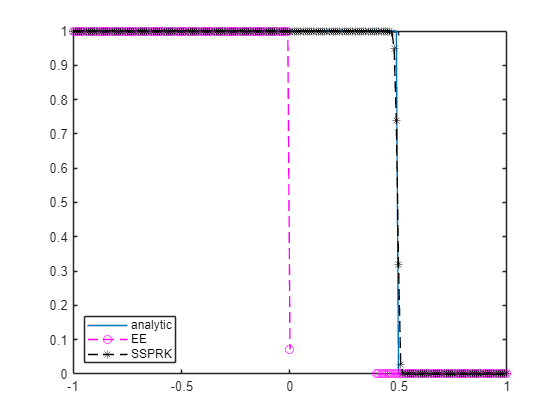

for i=1:N+1
    plot(xs, 1-heaviside(xs-ts(i)/2))
    hold on
    plot(xs, ys(:,i), 'mo--')
    plot(xs, ys2(:,i), 'k*--')
    legend('analytic', 'EE', 'SSPRK', 'Location', 'southwest')
    hold off
    pause(0.1)
    drawnow
end


% methods = ["explicitEuler", "midpoint", "heun", "SSPRK22", "ralston", "twoStepTest", "RK3", "heun3", "ralston3", "VDHW3", "SSPRK33", "RK4", "threeEighths", "ralston4", "SSPRK53", "SSPRK75", "SSPRK85", "SSPRK95", "SSPRK104"];
% plotSize = 10;
% for i = 1:length(methods)
%     if(i == 1)
%         A = [0];
%         b = [1];
%     else
%         [A, b] = getRK(methods(i));
%     end
%     [meshX, meshY, R_Z] = absStability(A, b, plotSize);
% 
%     %figure
%     contourf(meshX,meshY,1-abs(R_Z), [0 0], 'LineWidth', 1);
%     set(gca,'FontSize', 10, 'CLim', [0 1]);
%     colormap([.1 .5 .3; 0 0 0; 1 1 1]);
%     hold on;
%     plot([-plotSize plotSize], [0 0], '--k', 'LineWidth', 1);
%     plot([0 0], [-plotSize plotSize], '--k', 'LineWidth', 1);
%     hold off
%     axis('square');
%     fileName = strcat('absStab',string(i),'.pdf');
%     %saveToPicture(fileName);
% end

Function cemetery

function r = saveToPicture(fileName)
    h = gcf;
    set(h,'Units','Inches');
    pos = get(h,'Position');
    set(h,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)]);
    print(h, fileName,'-dpdf');
end